# Lab 2 -- How to use Statistical Functions and plot Histograms in MATLAB

#### Lab Section: 01

#### Team Members

#### Steven Bolt

### Team Lead

#### **Steven Bolt**

### **Objective:**

The objective of this activity is to gain experience using the statistical functions in MATLAB to process digital signals. 

###  **Intended Learning Outcomes: **

- Be able to use statistical functions in MATLAB to analyze data 

- Become familiar with using MATLAB commands: rand, max, min, mean, std 

- Use the histogram function to estimate and characterize the probability density function of random variable

- Analyze a dataset in terms of its signal to noise ratio

- Analyze the histogram of quantization noise for large and small signals relative to the quantization step size

### Procedure:

Follow the steps in each section of the Live script running each block as you go.  Be sure to answer the questions posed. You can answer these right in the text sections themselves.  You will submit your completed document as the MATLAB Live Script file and as an PDF file when you are completed.

## Part 1

Load the matlab datafile from myCourses "Lab2_Chapter2_Section1.mat" .  This will load two variables into the work space, 'sample' and 'signal'

% Clear the workspace and load the data file
clear
load Lab2_Chapter2_Section1.mat
[sample, signal];

### Step 1 Compute the Statistics

This file contains a variable called signal that has 730 samples.  Compute the maximum value (max), minimum value (min), average value (mean), standard deviation (std) and the variance ( square of the standard deviation) of the variable 'signal'. 

%  Create the variables below that represent the statistics of the variable signal
maxSignal = max(signal);
minSignal = min(signal);
avgSignal = mean(signal);
stdSignal = std(signal);
varSignal = stdSignal^2;

### Step 2  Create a Data Table

Create a table in MATLAB to display the values.  Use the 'table' function in MATLAB.   I've created the first table for you.  You can use this as a template to create later tables.  Use the help feature of MATLAB to look up how to enter values in a table.  The values of a column must be a column vector.  Use the Properties 'RowName' and 'VariableNames' to add row names and column names respectively.  Note that the list of row names and variable names must be a MATLAB cell array which is a data type that is enclosed by curly braces.  For example a = { 'first', 'second', 'third'} is a cell array.

% Create a column vector with the values for the table.
% Each value for the statistics is in one row
valuesForTable = [maxSignal; minSignal; avgSignal; stdSignal; varSignal];

%  Create the table.  Add Row Names and a Name for the column of values
statsTable = table(valuesForTable,...
    'RowNames',{'Maximum','Minimum','Average','Standard Deviation','Variance'},...
    'VariableNames',{'Values'})

statsTable = 5×1 table
                          Values
                          ______

    Maximum               76.411
    Minimum               20.417
    Average                48.15
    Standard Deviation     8.326
    Variance              69.322


### Step 3  Plot the Data

Plot the values of the varible 'signal' versus the variable 'sample'.  I have made the first plot for you.  Add a descriptive title,  and label the xaxis and the yaxis appropriately using the MATLAB commands 'title', 'xlabel' and 'ylabel' appropriately.  Turn on the grid

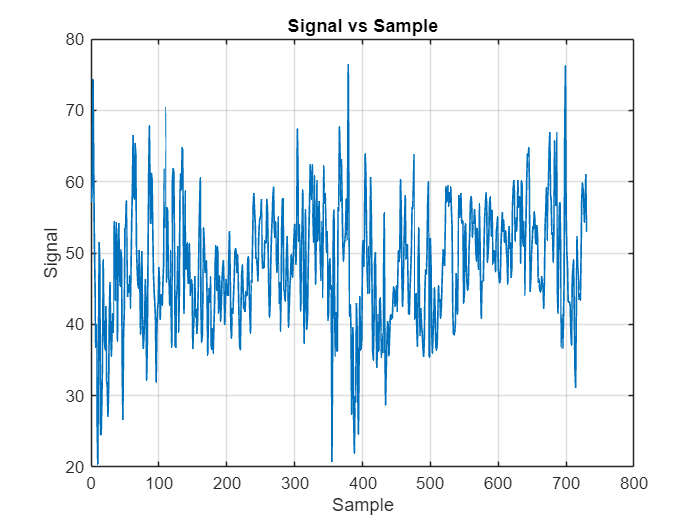

%  Plot the variable signal versus the variable sample.
%  Use the default line colors and style (blue and - )Use a larger
%  linewidth and turn on the grid.

figure
plot(sample, signal, 'LineWidth',1)
grid('on');
title('Signal vs Sample')
xlabel('Sample');
ylabel('Signal');

### Question 1

Anwer the following questions by typing directly in the text section of this Live Script.

Which statistical parameters can you estimate by just observing the samples on the graph?  Which ones can you not estimate?  Do the values that you estimate by observing the graph agree with the values that you computed?  Why or why not?

### Type your answer here:

You can get a good idea of the average, maximum, and minimum and they seem to line up relatively well with the computed values.

### Step 5  Create a Histogram

MATLAB has a function to create histograms of the data, 'histogram(y)'.  Use the MATLAB HELP to find more details on the function.

Use the MATLAB histogram function to plot the histogram of the signal.  Add a title, and label the x and y axes of the plot

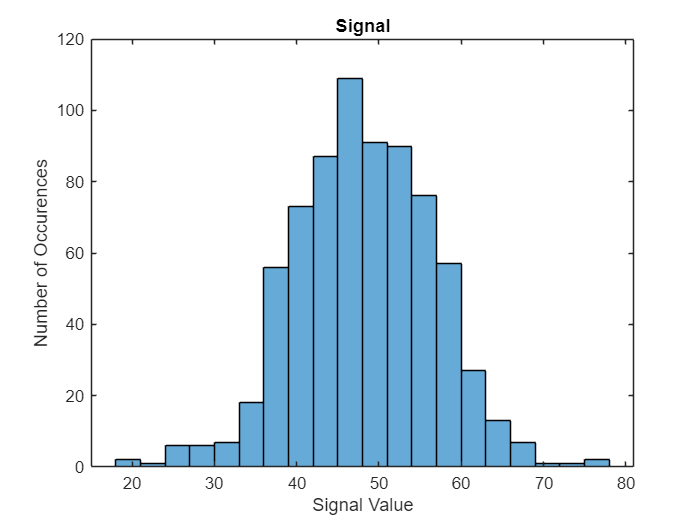

% Function to plot histogram with the same axis titles each time
function plotHistogram(data)
    histogram(data);

    xlabel('Signal Value')
    ylabel('Number of Occurences')
end

%  Plot a histogram of the signal data
plotHistogram(signal)
title('Signal')

#### Question 2

What probability distribution best describes the data (uniform, triangular, normal, other)?  Type your answer below.

#### Type your answer here:

Normal

Press the Button below to Run Part 1

## Part 2  Load Dataset 2

Load the matlab datafile from myCourses "Lab2_Chapter2_Section2.mat" .  This will load four variables into the work space, 'sample' and 'signal_1', 'signal_2', 'sumSignals'

%  Clear the workspace and load the data file
clear
load Lab2_Chapter2_Section2.mat
[sample, signal_1, signal_2, sumSignals];

### Step 1 Compute the Statistics

This file contains three variables.  The variables 'signal_1' and 'signal_2' and sumSignals have 730 samples each.  The variable 'sum_signals' is the sum of those two signals.  Compute the maximum value (max), minimum value (min), average value (mean), standard deviation (std) and the variance ( square of the standard deviation) of the variable 'signal'.  Repeat the calculations for signal 2.  Compute the same statistics for the variable sumSignals that is the sum of signal_1 and signal_2.

%  Create the variables below that represent the statistics of the variable signal
maxSignal_1 = max(signal_1);
minSignal_1 = min(signal_1);
avgSignal_1 = mean(signal_1);
stdSignal_1 = std(signal_1);
varSignal_1 = stdSignal_1^2;

%  Create another set for signal_2
maxSignal_2 = max(signal_2);
minSignal_2 = min(signal_2);
avgSignal_2 = mean(signal_2);
stdSignal_2 = std(signal_2);
varSignal_2 = stdSignal_2^2;

% Create another set for the sum of the signals
maxSumSignals = max(sumSignals);
minSumSignals = min(sumSignals);
avgSumSignals = mean(sumSignals);
stdSumSignals = std(sumSignals);
varSumSignals = stdSumSignals^2;

### Step 2  Create a Data Table

Create a table in MATLAB to display the computed statistics.  Use the code to create a table above as a template.  Copy, Paste and modify the code as needed.  Create a table that looks like the table in the figure below:

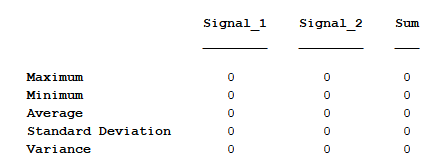

Use the 'table' function in MATLAB.   I've created the first column vector for you.  Create the other two and include the RowNames property and the VariableNames property.

% Create a column vector with the values for the table.
% Each value for the statistics is in one row
valSig1 = [maxSignal_1; minSignal_1; avgSignal_1; stdSignal_1; varSignal_1];
valSig2 = [maxSignal_2; minSignal_2; avgSignal_2; stdSignal_2; varSignal_2];
valSum = [maxSumSignals; minSumSignals; avgSumSignals; stdSumSignals; varSumSignals;];


%  Create the table.  Add Row Names and a Name for the column of values
statsTable = table(valSig1, valSig2, valSum,...
    'RowNames',{'Maximum','Minimum','Average','Standard Deviation','Variance'},...
    'VariableNames',{'Signal_1', 'Signal_2','Sum'})

statsTable = 5×3 table
                          Signal_1    Signal_2     Sum  
                          ________    ________    ______

    Maximum                 80.499     12.989     93.424
    Minimum                   79.5      3.009     82.644
    Average                 80.008     7.9344     87.943
    Standard Deviation      0.2885      2.945     2.9674
    Variance              0.083234     8.6732     8.8056


### Step 3  Plot the Data

Create an individual plot of each variable signal_1, signal_2 and sumSignal.  Properly label the title and the axes.  Scale the y-axes for all three graphs from 0 to 100 using the 'ylim' function.  For example ylim( [yMIn,yMax] ) where yMin and yMax are the minimum and maximum y-values.  Having the same axes for graphs that you are going to compare is very helpful to the reader.  Turn the grid on for all three graphs.  Use the plotting code from above as a starting point.  Copy and Paste as needed.  Create a new figure for each plot.

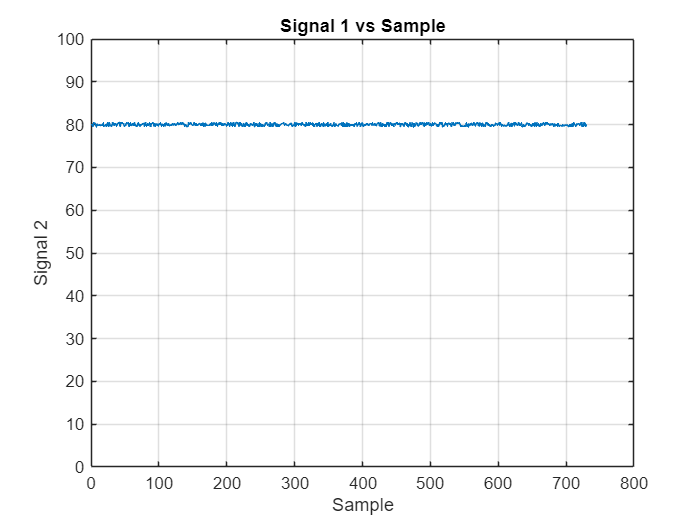

%  Plot the variables versus the variable sample.  Use the default line colors and style (blue and - )Use a larger
%  linewidth and turn on the grid

%  Signal 1
figure
plot(sample, signal_1, 'LineWidth', 1)
grid('on')
title('Signal 1 vs Sample')
xlabel('Sample')
ylabel('Signal 2')
ylim([0 100])

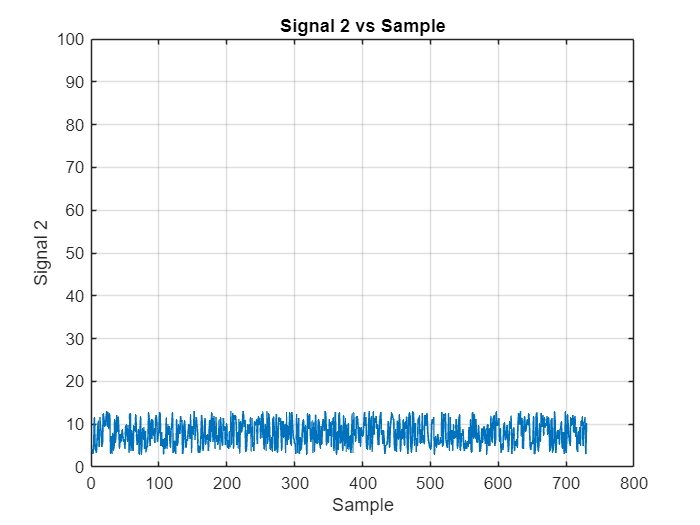

%  Signal 2
figure
plot(sample, signal_2, 'LineWidth', 1)
grid('on')
title('Signal 2 vs Sample')
xlabel('Sample')
ylabel('Signal 2')
ylim([0 100])

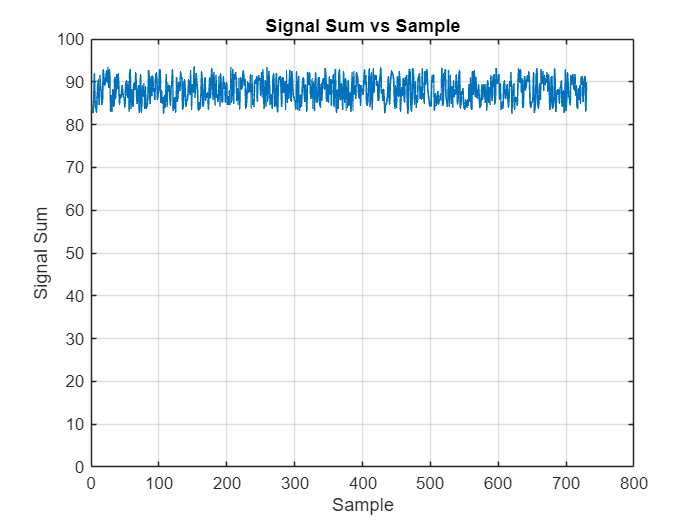

%  Sum of the two Signals
figure
plot(sample, sumSignals, 'LineWidth', 1)
grid('on')
title('Signal Sum vs Sample')
xlabel('Sample')
ylabel('Signal Sum')
ylim([0 100])

### Step 3  Plot the Histograms

Plot histograms of eah of the three variables.  Title and label the x and y axes appropriately

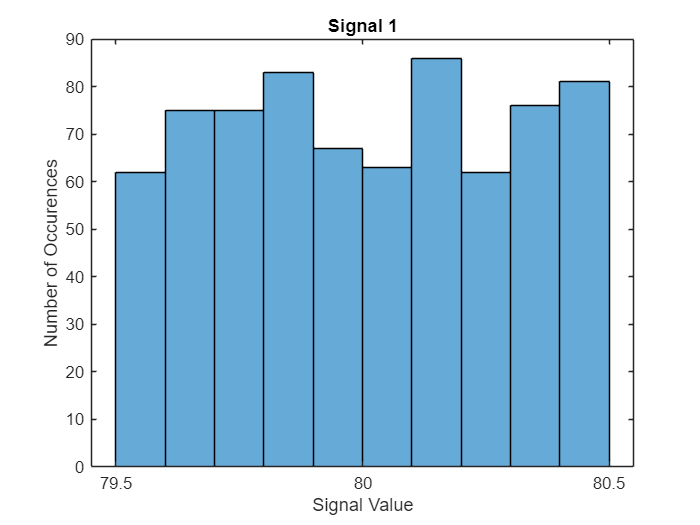

%  Plot a histogram of the signal data.

%  Signal 1
plotHistogram(signal_1)
title('Signal 1')

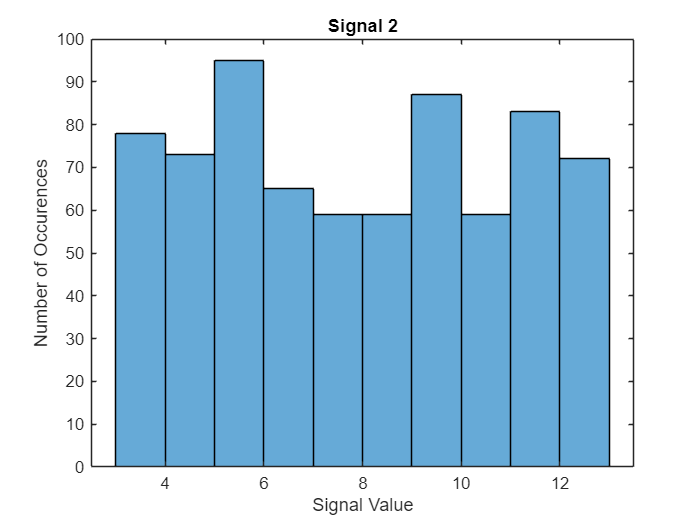

%  Signal 2
plotHistogram(signal_2)
title('Signal 2')

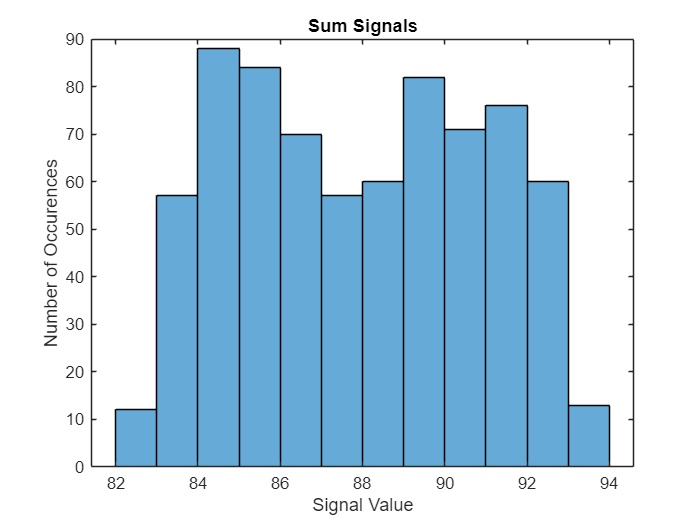

%  Sum of Signals
plotHistogram(sumSignals)
title('Sum Signals')

  Press the Button below to Run Part 2

#### Question 3

Theoretically, what should the mean of the sum of the signals be equal to? Is this the case for the data given? (exactly or approximately?) (Why, or Why not?)

The mean of the sum of the signals should be equal to the sums of the two individual signals, which seems to be exactly the case.

#### Question 4

Theoretically, what should the variance of the sum of the signals be equal to? Is this the case for the data given? (exactly or approximately?) (Why, or Why not?)

The variance of the sum of the signals should be equal to the sums of the two individual signals, which seems to be exactly the case.

#### Question 5

Is the standard deviation of the sum of the two signals (signal_1 + signal_2)  less than,  greater than or equal to the sum of the standard deviations of the individual components signal_1, signal_2? (exactly or approximately?) (Why, or Why not?)

The standard deviation of the sum of the two signals is less than the direct sum of the standard deviations of the two individual signals. This is because standard deviations add in quadrature.

#### Question 6

What probability distribution best describes the data in the histogram of the sum of the signals (uniform, triangular, normal, other)?

The histogram data seems to be bimodal.

### Comments on Part 2

It is important to note that in all the analysis you’ve just done the specific values for standard deviation, mean, and so forth will change as the random numbers change. In the data file you were given a fixed set of random numbers, but in reality, each time you run such a test the random noise changes and your answers will change slightly. You are only estimating the true mean and the true standard deviation from a finite set of data points. Thus, you will have some typical error between this value and the true mean.  The typical error is the error of the estimate of the mean.

## Part 3  Creating and Computing Statistics of Random Numbers

### Step 1

In this part, you will use the MATLAB rand() function to create 12 unform random variables that range from 0 to 1 and have a mean of 0.5.  This will be done using a matrix in MATLAB.  Recall that you can create a matrix of M rows by N columns of random variables using rand(M, N).  You will then create a variable that is the sum of the first two random variable columns and an additional variable that is the sum of all 12 variables.  You will investigate the properties of those variables.

%  Create 12 uniformly distributed random variables with 2000 values for
%  each variable.  Make each variable a column with 2000 rows
%  Use the MATLAB rand( rows, columns ) function
randNums = rand(2000, 12);

### Step 2

Plot the histogram of the uniform random numbers in the first column.  Add a title and axes labels

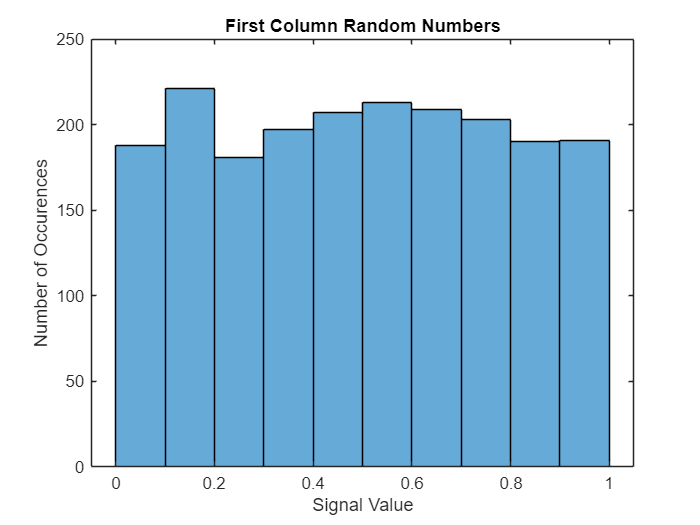

%  The histogram of the first random variable
plotHistogram(randNums(:,1))
title('First Column Random Numbers')

### Step 3

Create a variable that is the sum of the first two columns.  Recall that you can select a single column from a matrix using the : operator.  That  is  x = M( :, 2) selects all the values in the second column of the matrix M 

%  Create a variable that is the sum of the first two columns.  
sumCol1Col2 = randNums(:, 1) + randNums(:, 2);

### Step 4

Plot the histogram of the sum of the two random variables

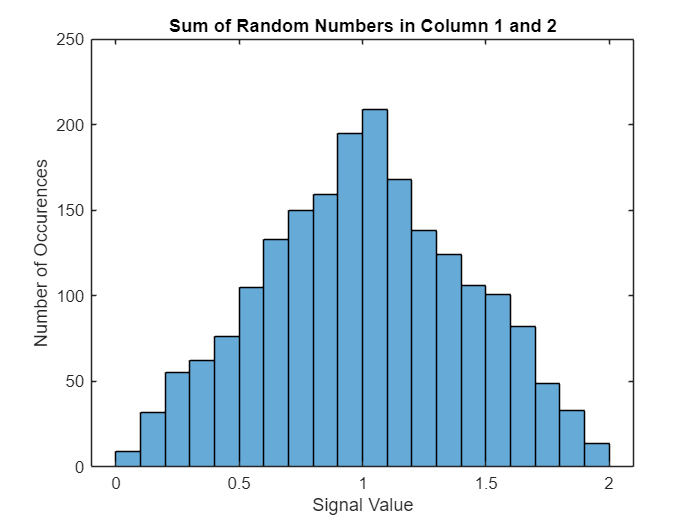

%  The histogram of the first sum of two uniform random variables
plotHistogram(sumCol1Col2)
title('Sum of Random Numbers in Column 1 and 2')

### Step 5

Create a variable that is the sum of all 12 random variables in the matrix.  That is the sum of all the values in each row.  The MATLAB sum function will sum all the values of a matrix across a selected DIMENSON.  You can sum the rows by taking the sum across the second dimension (that is rows). y =sum( x, 2)  You can take the sum of the values in a column by taking the sum of the first dimension (that is columns).  For example y = sum(x,1).  The result of the sum should be a matrix with 1 column of length 2000.

%  Create a variable that is the sum of all 12 random variables
sumAllCols = sum(randNums, 2);

### Step 6

Plot the histogram of the sum of the 12 random variables

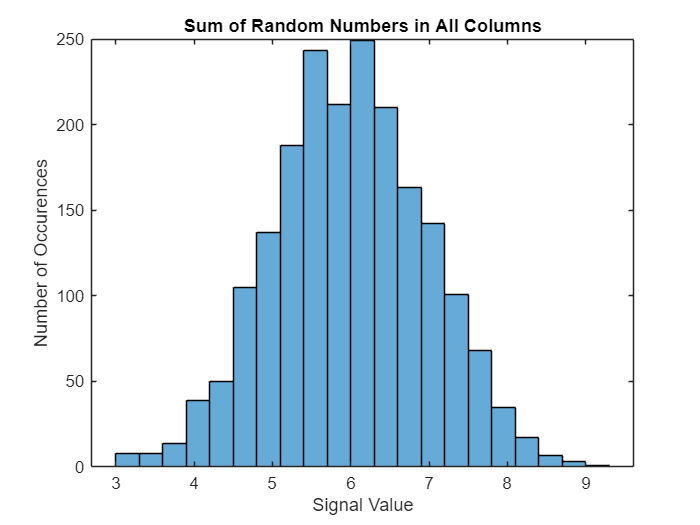

%  The histogram of the sum of 12 uniform random variables
plotHistogram(sumAllCols)
title('Sum of Random Numbers in All Columns')

   Press the Button below to Run Part 3

#### Question 7

Carefully compare the distributions (from the histogram) of a single uniform random variable, the sum of two uniform random variables and the sum of 12 uniform random variables.  How are each of these distributions best described (uniform, triangular, normal, other)? How does this compare to theory? What theory applies to the sum of the 12 signals?

#### Type your answer here:

The single variable is uniform, the sum of two columns is normal, and the sum of all columns is even more normal. This makes sense because as you add more and more random processes together, the sum becomes more normally distributed. This is the Central Limit Theorem.

## Part 4 Estimating Temperature Cycles

### Step 1

Load the matlab datafile from myCourses "Rochester_Average_Temp.mat".  This is data for the average daily temperature in Rochester in degress Fahrenheit over a two year period.  This will load four variables into the work space, 'sample' and 'msrdTemp', 'estTemp', 'error'

%  Clear the workspace and load the data file
clear
load Rochester_Average_Temp.mat
[sample, msrdTemp, estTemp, error];

### Step 2

Plot the values of the measured temperature 'msrdTemp' over a two year period.  Add appropriate title and axes labels.

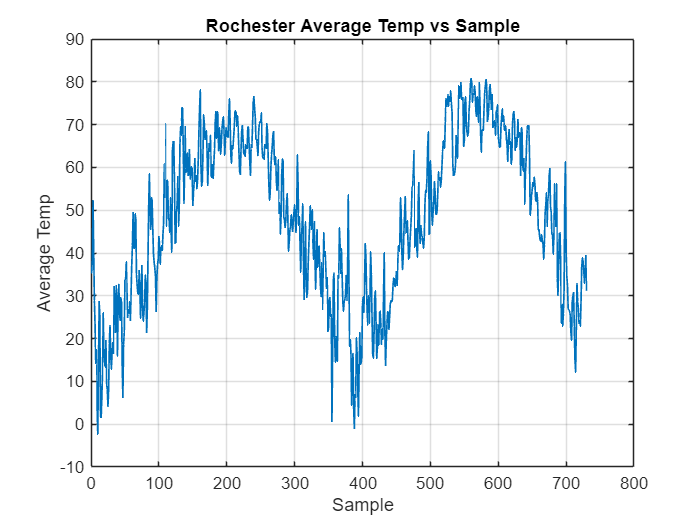

%  Plot of the average temperature in Rochester over a two year period
figure
plot(sample, msrdTemp, 'LineWidth', 1)
grid('on')
title('Rochester Average Temp vs Sample')
xlabel('Sample')
ylabel('Average Temp')

### Step 3

The daily average temperature can be estimated by a constant value of 48.2 F plus a sinusoidal variation of amplitude 23 degrees F and phase of -1.9 radians. Putting this all together, the estimated temperature is: 

Daily average temperature (F)  = 48.2+23*SIN((2*PI()*day/365)-1.9) 

The estimated daily temperature value is  already computed in the variable 'estTemp'. The error between the actual measured data and the estimated data is in the variable 'error'.

Plot the error of the estimator.  Add title and axes labels

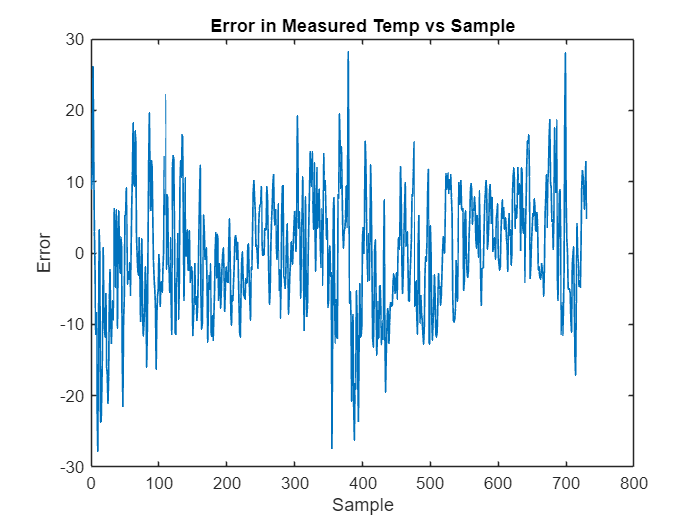

%  Plot of the error of the measured and average temperature in Rochester over a two year period.
%  Add a grid

figure
plot(sample, error, 'LineWidth', 1)
title('Error in Measured Temp vs Sample')
xlabel('Sample')
ylabel('Error')

### Step 4

Plot the histogram of the error in temperature.  Add titles and label the axes.

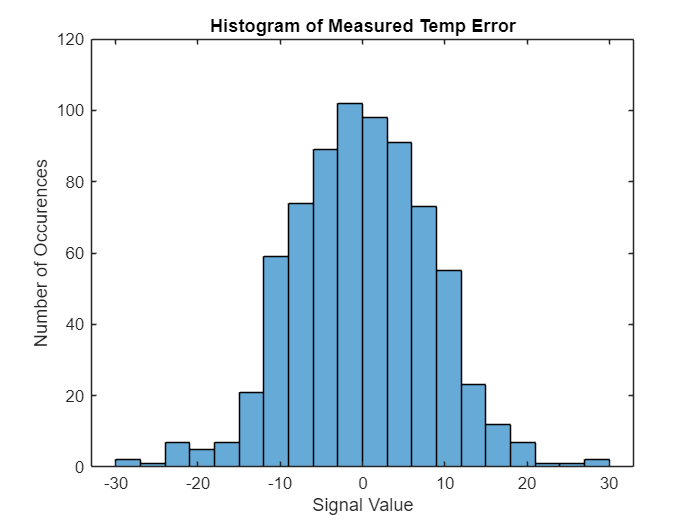

%  The histogram of the temperature error
plotHistogram(error)
title('Histogram of Measured Temp Error')

### Step 5

Compute the standard deviation of the temperature error

%  The standard deviation of the error temperatures
stdError = std(error)

stdError = 8.3260

#### Question 8

How would you describe the distribution of the error of the estimate (normal, uniform, triangular, other)?

#### Type your answer here:

Normal

### Step 6

If the estimator predicts that the temperature today will be 55 degrees, what is the signal to noise ratio of this estimate, Given that the standard deviation of the error was the value you just calculated?   What is the value of the signal considered to be?

%  Signal to noise ratio calculation
sigNoiseRatio = 55 / stdError

sigNoiseRatio = 6.6058

   Press the Button below to Run Part 4

## Part 5  Quantization Noise -- Uncorrelated Signal

### Step 1

Load the matlab datafile from myCourses "Quantized_Signal_1.mat".  This is data for a continuous sinusoidal signal and one that is quantized with a quantization size of 1.  Four variables are loaded into the MATLAB workspace

sample -- the sample number

conSignal -- The high resolution continuous sinusoidal signal

qSignal -- The quantized sinusoidal signal

error -- The error between the continuous signal and the quantized signal

The formula for the sinewave is: = 127.5 + 127.5*sin( sample / 10 )

The sinewave is **not** tightly correlated with the sampling frequency. 

Plots of the signals are made for you below

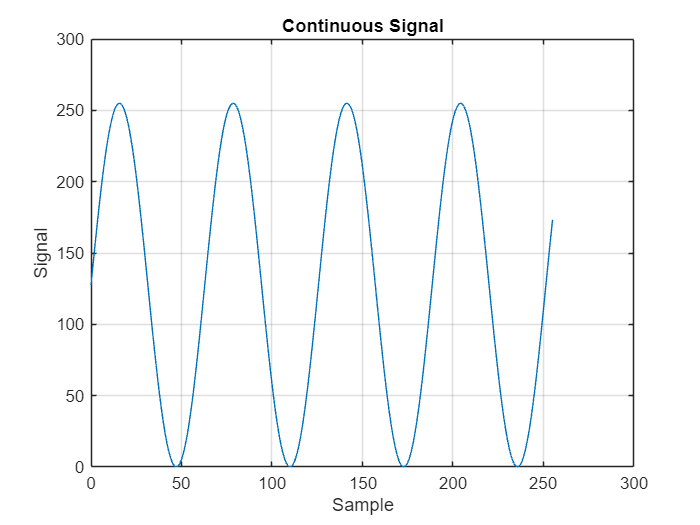

%  Clear the workspace and load the data file
clear
load Quantized_Signal_1.mat
[sample, conSignal, qSignal, error];

%  Plot continuous signal
figure
plot(sample, conSignal)
grid on
title('Continuous Signal')
xlabel('Sample')
ylabel('Signal')

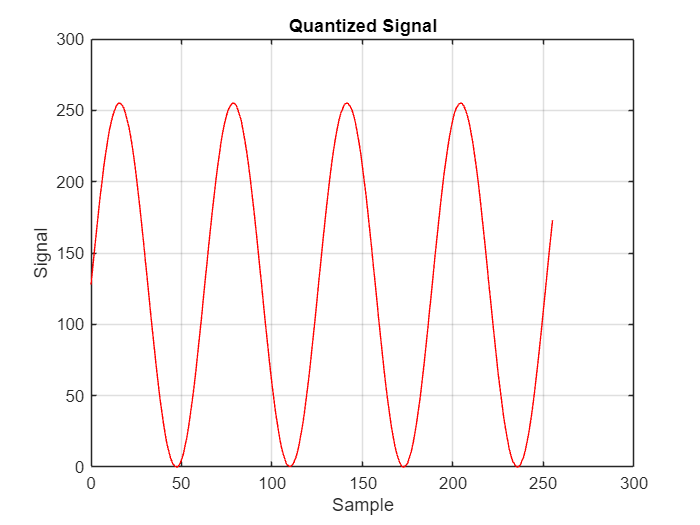

% Plot quantized signal
figure
plot(sample, qSignal,'r')
grid on
title('Quantized Signal')
xlabel('Sample')
ylabel('Signal')

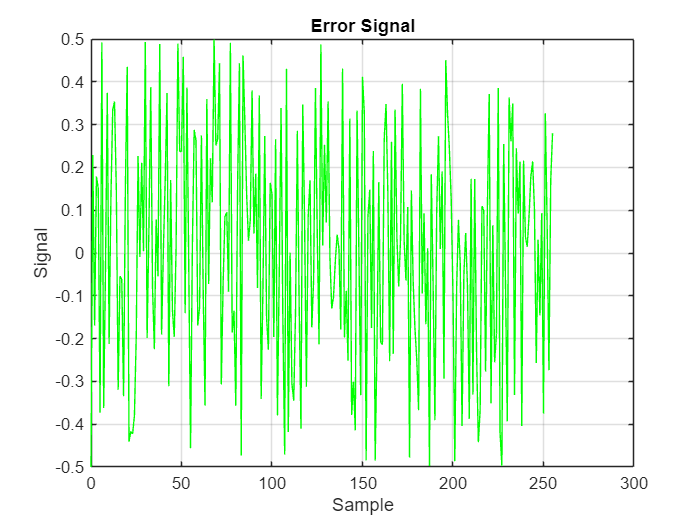

% PLot error signal
figure
plot(sample, error,'g')
grid on
title('Error Signal')
xlabel('Sample')
ylabel('Signal')

### Step 2

Plot a histogram of the quantization error using the histogram bins edges given in the variable 'binEdges' in the code section.  The option to add bin edges is:

histogram( x, binEdges )

Then create a  historgram showing the cumulative values by adding the PropertyName 'Normalization' with a value of 'cdf'.  This represents the cumulative density function of the data.

example

histogram(x, binEdges, 'Normalization','cdf')

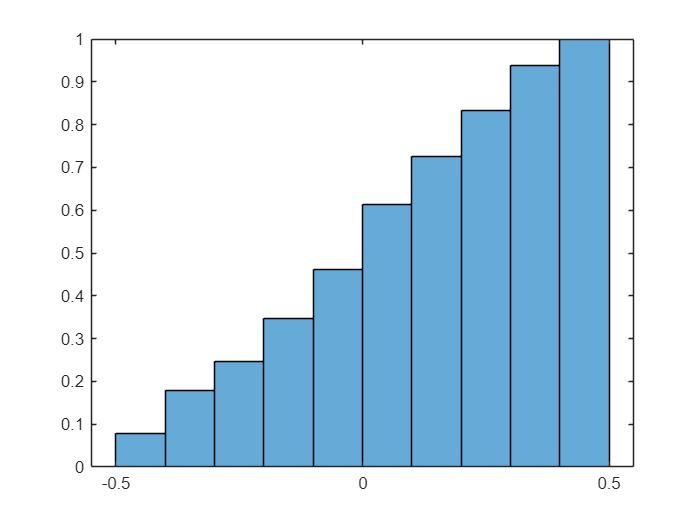

%  Plot the histogram of the quantization error
binEdges = -0.5:0.1:0.5;
histogram(error, binEdges, 'Normalization', 'cdf')

   Press the Button below to Run Part 5

#### Question 11

How would you describe the distribution of the error of the estimate (normal, uniform, triangular, other)?  What do you observe about the cumulative density function and how does it relate to the histogram of the data?

#### Type your answer here:

The distribution seems to skew right in triangular distribution.

## Part 6  Quantization Noise -- Correlated Signal

### Step 1

Load the matlab datafile from myCourses "Quantized_Signal_2.mat".  This is data for a continuous sinusoidal signal and one that is quantized with a quantization size of 1.  Four variables are loaded into the MATLAB workspace

sample -- the sample number

conSignal -- The high resolution continuous sinusoidal signal

qSignal -- The quantized sinusoidal signal

error -- The error between the continuous signal and the quantized signal

The formula for the sinewave is: = 127.5 + 127.5*sin( 2*pi*sample / 64 )

The sinewave **is** tightly correlated with the sampling frequency. 

Plots of the signals are made for you below

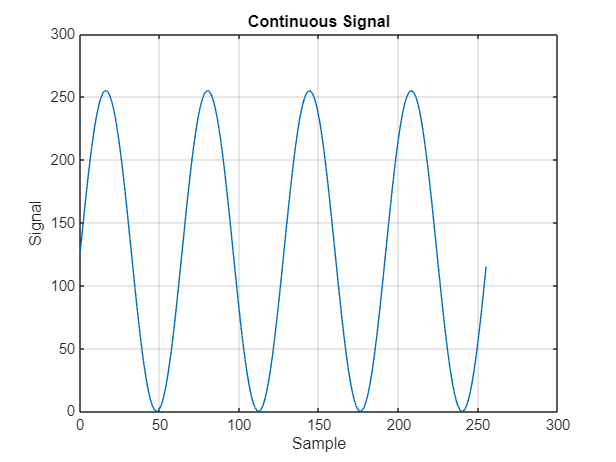

%  Clear the workspace and load the data file
clear
load Quantized_Signal_2.mat
[sample, conSignal, qSignal, error];

%  Plot continuous signal
figure
plot(sample, conSignal)
grid on
title('Continuous Signal')
xlabel('Sample')
ylabel('Signal')

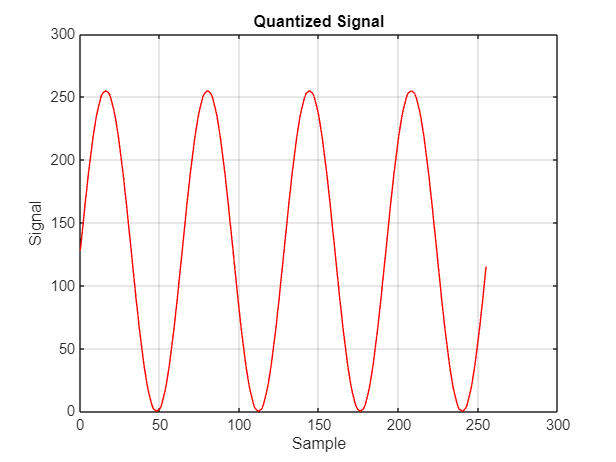

% Plot quantized signal

figure
plot(sample, qSignal,'r')
grid on
title('Quantized Signal')
xlabel('Sample')
ylabel('Signal')

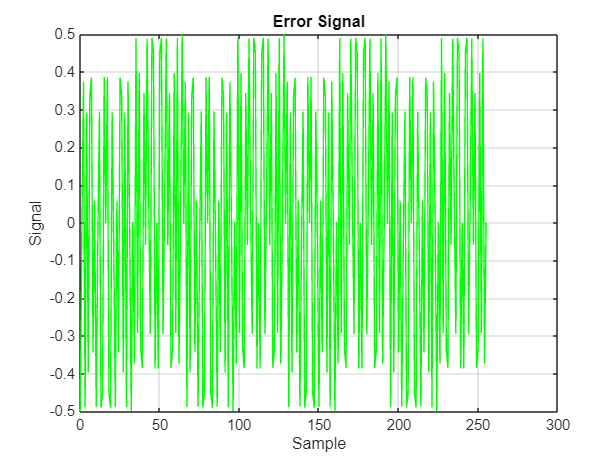

% Plot error signal

figure
plot(sample, error,'g')
grid on
title('Error Signal')
xlabel('Sample')
ylabel('Signal')

### Step 2

Plot a histogram of the quantization error using the histogram bins edges given in the variable 'binEdges' in the code section.  The option to add bin edges is:

histogram( x, binEdges )

Then create a  historgram showing the cumulative values by adding the PropertyName 'Normalization' with a value of 'cdf'.  This represents the cumulative density function of the data.

example

histogram(x, binEdges, 'Normalization','cdf')

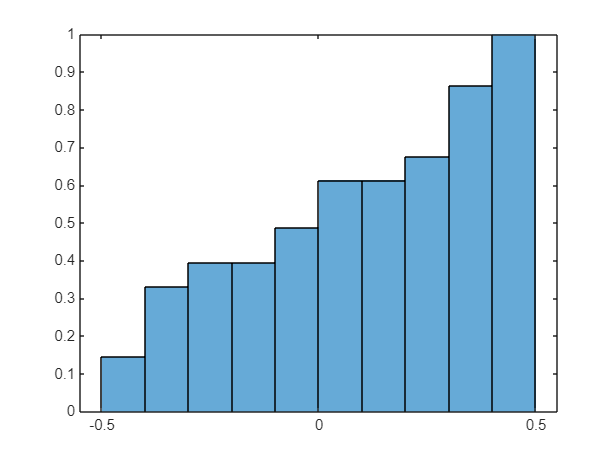

%  Plot the histogram of the quantization error
binEdges = -0.5:0.1:0.5;
histogram(error, binEdges, 'Normalization', 'cdf')

   Press the Button below to Run Part 6

#### Question 12

How would you describe the distribution of the error of the estimate (normal, uniform, triangular, other)?

#### Type your answer here:

Triangular.

#### Question 13

Are the distributions of the quantization error significantly different or largely the same between the correlated and the uncorrelated signals?

#### Type your answer here:

Largely the same.

When the sample rate and the signal are correlated with one another, the distribution of the quantization error may not look uniform as it does when the sample and the signal rate are uncorrelated with one another.

## Part 7  Typical Error

When we take multiple samples from a random process with noise the individual sample values will vary in value.  The mean of all the samples that we take will be an estimate of the true mean of the process.  This estimate of the mean has some amount of error to the true mean of the process.  We define a quantity called the "typical" error.  We can find the typical error by computing multiple estimates of the mean and finding the standard deviation of all those estimates.  The standard deviation is what we call the typical error of the estimate.

We can decrease the typical error (decrease the standard deviation) of the estimate by including more samples in our estimate of the mean.  For example the typical error of the estimate when I use 100 samples of the process in computing the estimate of the mean will be smaller than the typical error when I use 10 samples of the process in computing the estimate of the mean.

The typical error or standard deviation of the estimate improves inversely proportional to the square root of the number of samples used in the estimate.  That is:


$$\sigma_{n} = \frac{\sigma_{process}}{\sqrt{n}}$$


where $\sigma_{n}
$ is the standard deviation of the mean estimate when using n samples to compute the estimate.  This equation indicates that the standard deviation of the estimate using N samples is equal to the process standard deviation divided by the square root of the number of samples in the estimate.

### Step 1

In this part of the lab you will simulate computing the estimate of the mean of a process using 1 sample from that process.  You will calculate the typical error (using the standard deviation). Then you will simulate computing the estimate of the mean of the process using a larger number of samples to reduce the typical error to a specified amount.  You will determine the number of samples required to reduce the typical error to an acceptable level.  The code for the first step is done for you.  Take a look to see how it is done.

%  Clear the workspace 
clear

% ------------Process parameters------------ %
% True process mean -- The signal is a fixed value that has a fixed true mean
trueMeanProcess = 3.5;

%  Standard deviation of the process.  The process has noise on it that is
%  normally distributed.  The value of the standard deviation is .001.
sigmaProcess = .001;

%  Number of trials -- The number of trials is the number of estimates of the mean that you will compute
%  This is not the number of samples used in the mean estimate, just the number
%  of estimates.  We look at a large number of estimates to see how they
%  differ from one another.
numTrials = 1000;

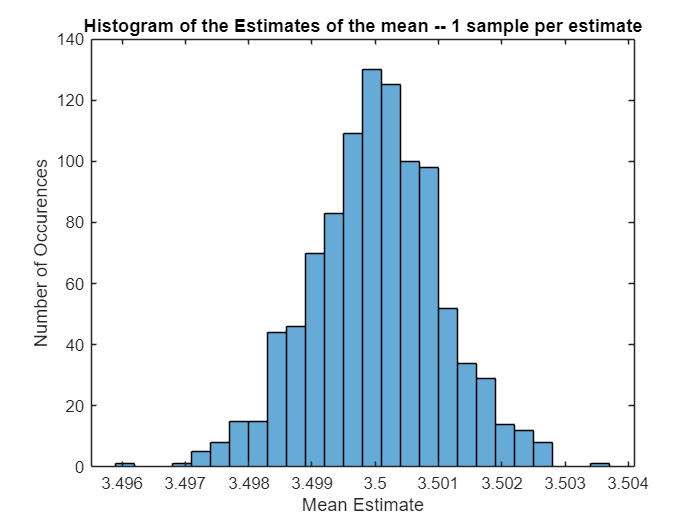

%  Number of samples taken for each estimate
%  This is the number of samples that are used to compute the estimate.
%  We'll start with by using one sample to estimate the process mean
numSamplesPerEstimate = 1;

%  Compute 'numTrials' estimates of the mean of the process.  For each trial use numSamples to compute the
%  estimate.  Use a 'for' loop for this (not very MATLABian however :-(  )

%  Clear the matrix of estimates of the mean that will be computed.  We'll
%  save all the values that we estimate
meanEstimate = [];

for iTrial = 1:numTrials
    
    %  Create numSamplesPerEstimate samples of the process    
    processSamples = sigmaProcess * randn(numSamplesPerEstimate,1) + trueMeanProcess;
    
    % Now take the average of those samples
    meanEstimate(iTrial) = mean(processSamples);

end

%  Find the typical error of the mean estimate.  Plot a histogram
typicalError = std(meanEstimate);

figure
histogram(meanEstimate)
title('Histogram of the Estimates of the mean -- 1 sample per estimate')
xlabel('Mean Estimate');
ylabel('Number of Occurences');

### Step 2

Calculate the number of samples required to compute the estimate of the mean in order to keep the typical error of the mean estimate below $100\times10^{-6}
$ .  The standard deviation of the mean estimate using 1 sample from the process for each estimate should be $1\times10^{-3}
$.  Is that the value that you computed?

Recall that the typical error of the estimate of the mean is:


$$typical\ error=\sigma_{estimate} =\sigma /\sqrt{N}$$


Solve for the value of N, the number of samples to use in the mean estimate computation


$$N = (\frac{\sigma_{process}}{\sigma_{est}})^2$$


% Typical error check for a single sample, should be 1 x 10^-3
sigmaEstSingle = sigmaProcess / sqrt(1)

sigmaEstSingle = 1.0000e-03

% Want to keep the mean estimate below this value
sigmaEstDesired = 100 * 10^-6;

%  Solve for the number of samples required to achieve the desired typcial error of the
%  mean estimates
N = (sigmaProcess / sigmaEstDesired)^2

N = 100.0000

### Step 3

Estimate the true mean using the number of samples that you computed above. Copy the code from above that finds the estimate of the mean from the process using 1 sample from the process.  Then change the paramters to use the number of samples that you computed above.  

Change the name of the variable meanEstimate to something different so that you can save both sets of values and plot both histograms on top of one another for comparison

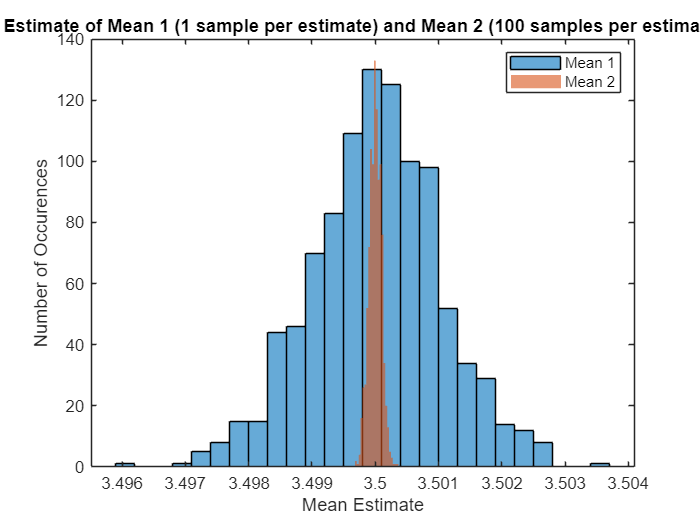

% Process parameters taken from step 1

%  Number of samples taken for each estimate
%  This is the number of samples that are used to compute the estimate.
%  We'll start with by using one sample to estimate the process mean
numSamplesPerEstimate = 100;

%  Compute 'numTrials' estimates of the mean of the process.  For each trial use numSamples to compute the
%  estimate.  Use a 'for' loop for this (not very MATLABian however :-(  )

%  Clear the matrix of estimates of the mean that will be computed.  We'll
%  save all the values that we estimate
meanEstimate2 = [];

for iTrial = 1:numTrials

    % Create numSamplesPerEstimate samples of the process    
    processSamples = sigmaProcess * randn(numSamplesPerEstimate,1) + trueMeanProcess;
    
    % Now take the average of those samples
    meanEstimate2(iTrial) = mean(processSamples);

end

%  Find the typical error of the mean estimate
typicalError2 = std(meanEstimate2);

%  Plot the histogram of both results
%  1.) Plot the histogram of the variablemeanEstimate
%  2.) Use 'hold on'
%  3.) Plot the histogram of meanEstimate2, the estimates of the 
%      mean using your number of samples per estimate.

% Plot histogram of first result
histogram(meanEstimate)
hold on;

% Plot histogram of second result
histogram(meanEstimate2, 'EdgeAlpha', 0)

% Graph properties
title('Estimate of Mean 1 (1 sample per estimate) and Mean 2 (100 samples per estimate)')
xlabel('Mean Estimate');
ylabel('Number of Occurences');
legend('Mean 1', 'Mean 2')

   Press the Button below to Run the code in Part 7

### Question 14

Describe the similarities and differences in the histograms of the mean estimates when you use 1 sample of the process for the estimate vs the number of samples that you computed to reduce the typcial error of the estimate.  What is the significance in the differences between the histograms?  What is the significance of the similarities between the two histograms?

Did the typical error of the estimate decrease to the specified values after changing the number of samples for each estimate?

Did the process change, or did the way you were estimating the mean of the process change?

#### Type your answer here:

The main difference between the graphs of the estimate taken with 1 vs 100 samples is the spread. The spread of the mean estimate with 100 samples is much tighter than with 1 sample. I believe that the siginificance of this is that the mean with 100 samples per estimate is much more precise than the mean with 1 sample. Both histograms have a normal distribution, which signifies that the data is truly random.

The typical error did successfully decrease to about the desired amount.

The process to estimate the mean did not change.

# Report Requirements

Save this file as a PDF file (FILE/Export to pdf) or first export to Word then save the Word file as a PDF.  Submit your completed MATLAB Live Script file and the PDF to the Assignments section of myCourses for Lab2.  Review your PDF file before submitting to insure that all your graphs have rendered correctly.  

Make sure that you include your team member names at the top of this file.

Make sure that you use the file naming convention with the Lab section and group name for example: Lab01_GroupName_Lab2.mlx